**AWG HOST INTERFACE**

This script controls the parameters and programs to be loaded to a AWG implemented on the Zynq-RFSoC FPGA for control of a qubit.

% Start-up settings
clear
clc
set(groot, 'defaultTextInterpreter', 'latex');

% Receiver commands. Constants for decoding UART messages, one-hot. Don't change!
LOAD_CMD   = 0x1;
FREQ_CMD   = 0x2;
PHASE_CMD  = 0x4;
RES_CMD    = 0x8;
AMP_CMD    = 0x10;
WIDTH_CMD  = 0x20;
ENABLE_CMD = 0x40;
PULSES_CMD = 0x80;
RATE_CMD   = 0xC0;

% Define COM port and Baud rate
port_name = "COM9";
baud_rate = 115200;
% UART transmission, 1 byte at a time. Re-run after each transmission.
port = serialport(port_name, baud_rate, "Timeout", 8);

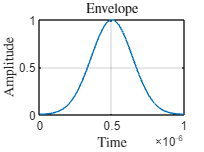

% Define envelope, default Gaussian

tp = 1e-6;          % 1 us pulse width is minimum
fclk = 409.6e6;     % Zynq boardclock
n_s = 3.5;            % Number of standard deviations to be included

[t, signal] = gauss(fclk, tp, n_s);
plot(t, signal);
title(("Envelope"))
xlabel("Time")
ylabel("Amplitude")
grid

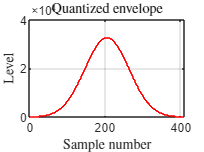

% Discretize envelope for signed binary representation
N = 16; % Number of bits
data = zeros(1, numel(signal));

for i = 1:length(signal) 
    if (signal(i) >= 0) 
        data(i) = round(signal(i)*(2^N/2)-1);
    else
        data(i) = round(signal(i) * (2^N)/2);
    end
end
stairs(1:length(t), data, 'r');
title("Quantized envelope")
xlabel("Sample number")
ylabel("Level")
grid

% Parameters
amp_percent = 100;  % Select amplitude (%). 
phase = 0;       % Select phase in radians.
res = 3;           % Select resolution in bits (1-14)
fc_offset = 20;      % Select carrier freqency offset (MHz) for IF IQ mixer
freq_off_dir = 0;   % '0' = lower sideband, '1' = upper sideband
tp = 1;             % Select pulse width (us), minimum 1 us (time resolution 1 us as well)
wait_time = 10000;    % Select repetion rate (us) between AWG programs, 400 us default.
num_pulses = 10000;  % Select number of pulses in program

% Convert amplitde to integers (0-511)
amp = round(amp_percent/100 * 511);

% Convert to FSW
FSW = (fc_offset*1e6*2^(10))/fclk;

% Store freq_off_dir in MSB of freq_offset
fsw_bin = dec2bin(FSW, 16);
freq_off_dir_bin = dec2bin(freq_off_dir);
freq_message = strcat(freq_off_dir_bin, fsw_bin(7:16));
fsw = bin2dec(freq_message);

% Compute phase idx
if (freq_off_dir)
    phase_idx = round((360.0-phase)*256.0*(360.0^(-1)));
else
    phase_idx = round((phase+90.0)*256.0*(360.0^(-1))-2.0);
end

% Load waveform 1 byte at a time

write(port, LOAD_CMD, "uint8"); % Send load command first
pause(0.01);

for i = 1:numel(data)
    [word1, word2] = byte_split(data(i));
    write(port, word1, "uint8");
    pause(0.01);
    write(port, word2, "uint8");
    pause(0.01);
end
write(port, ENABLE_CMD, "uint8");
disp("Waveform loaded");

Waveform loaded


% Load parameters

send_parameters(port, fsw, phase_idx, res, amp, tp, num_pulses, wait_time);

disp("All parameters loaded");

All parameters loaded


% Save program parameters in text file
save_param(amp_percent,phase,tp,res,fc_offset);


% sweep amplitude
for i = 1:5
sweep_amp(port, 5, 0, 511);
end

% sweep resolution
for i =1:5
sweep_res(port, 1, 1, 13);
end

% sweep pulse width
for i = 1:5
    sweep_width(port, 2, 1, 12);
end

% Sweep frequency offset in MHz
for i = 1:5
    sweep_freq_offset(port,freq_off_dir, fclk, 2, 0, 40);
end